Fundamentos de control                                                                                                                                                                                                       

# Introducción a MATLAB

### Gráficos

Uno de los puntos fuertes de MATLAB es el amplio abanico de posibilidades que ofrece a la hora de mostrar visualmente, en forma de gráficas, los datos con los que se está trabajando. Vamos a ver alguna de las opciones más comunes, ya que el estudio de la totalidad de funcionalidades ofrecidas requeriría de una asignatura completa para ello. A lo largo de la asignatura iremos descubriendo más posibilidades. 

## `1. Uno para gobernarlos a todos: plot`

El comando **plot** se postula como uno de los más usados a la hora de generar gráficos bidimensionales. Veamos su documentación:

help plot

 plot - 2-D line plot
    This MATLAB function creates a 2-D line plot of the data in Y versus the
    corresponding values in X.

    Vector and Matrix Data
      plot(X,Y)
      plot(X,Y,LineSpec)
      plot(X1,Y1,...,Xn,Yn)
      plot(X1,Y1,LineSpec1,...,Xn,Yn,LineSpecn)
      plot(Y)
      plot(Y,LineSpec)

    Table Data
      plot(tbl,xvar,yvar)
      plot(tbl,yvar)

    Additional Options
      plot(ax,___)
      plot(___,Name,Value)
      p = plot(___)

    Input Arguments
      X - x-coordinates
        scalar | vector | matrix
      Y

Como podemos comprobar permite, entre otras cosas:

- dibujar las columnas de un vector Y frente a sus índices (orden en el que aparecen en el vector, comenzando por el índice 1):

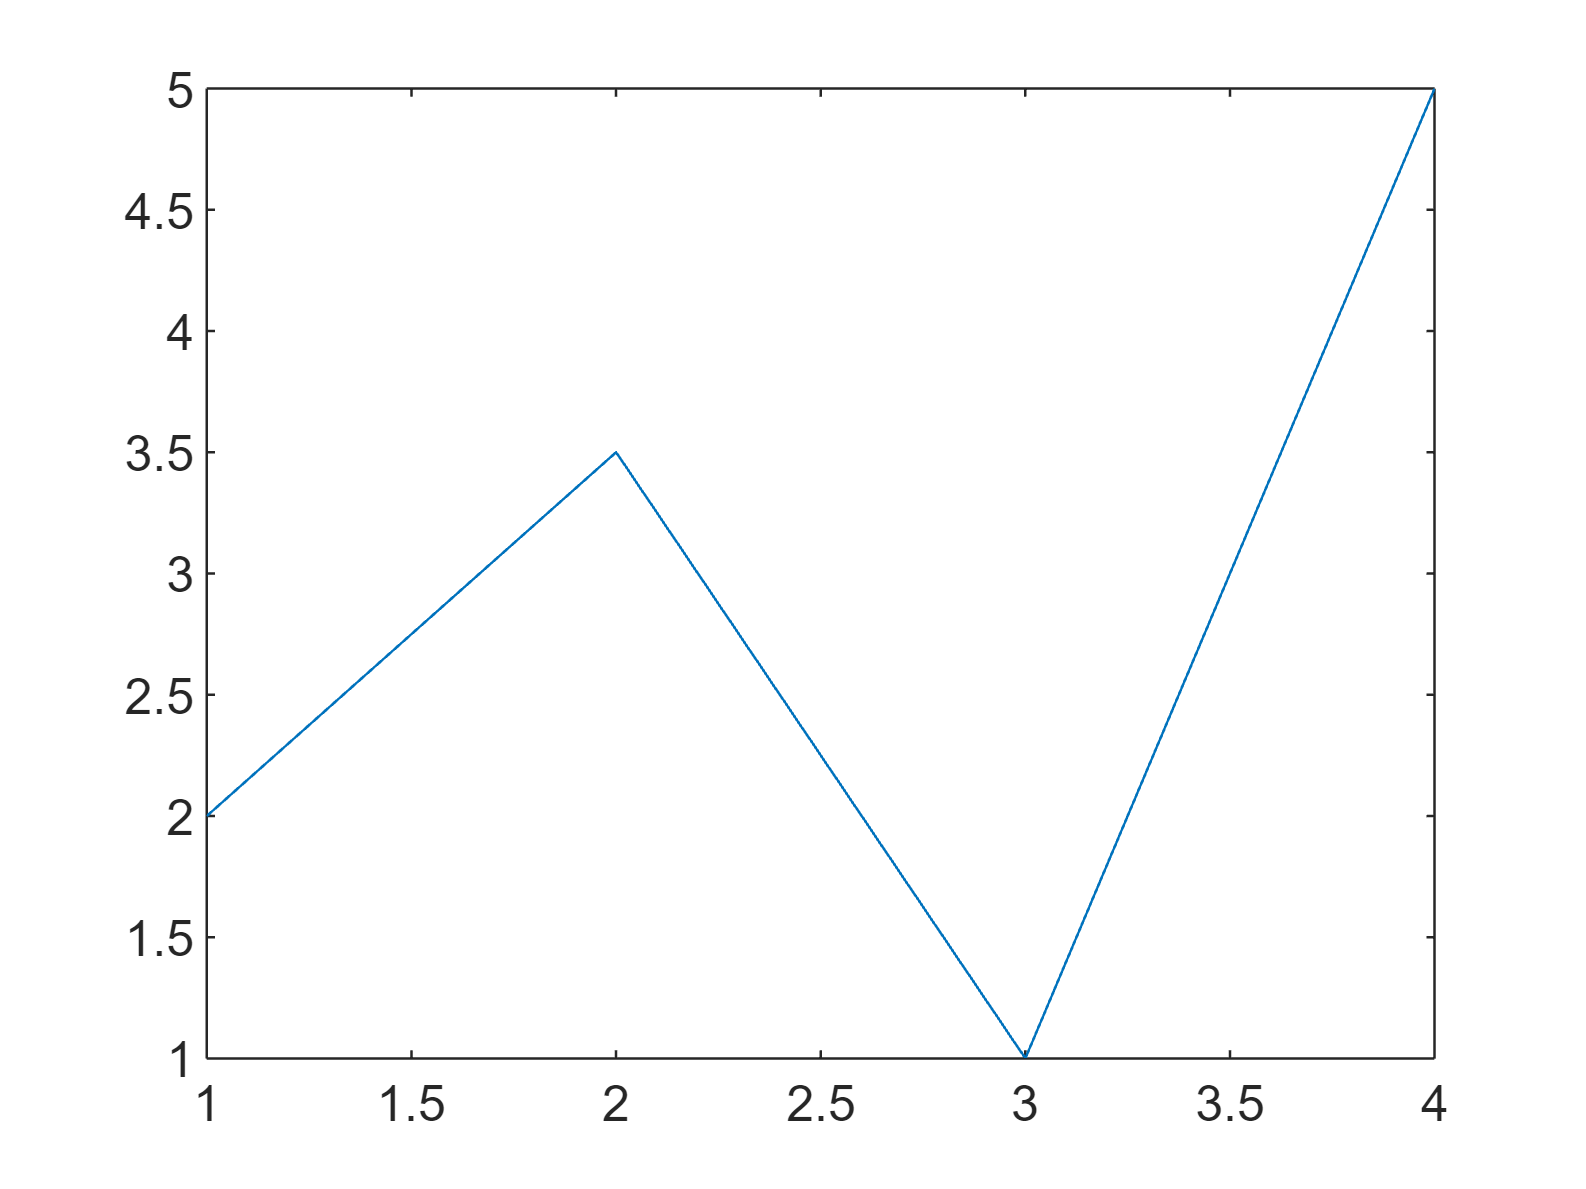

Y = [2 3.5 1 5];
plot(Y) 

-  dibujar un vector X frente a otro Y. Ejecuta el siguiente ejemplo para comprobarlo:

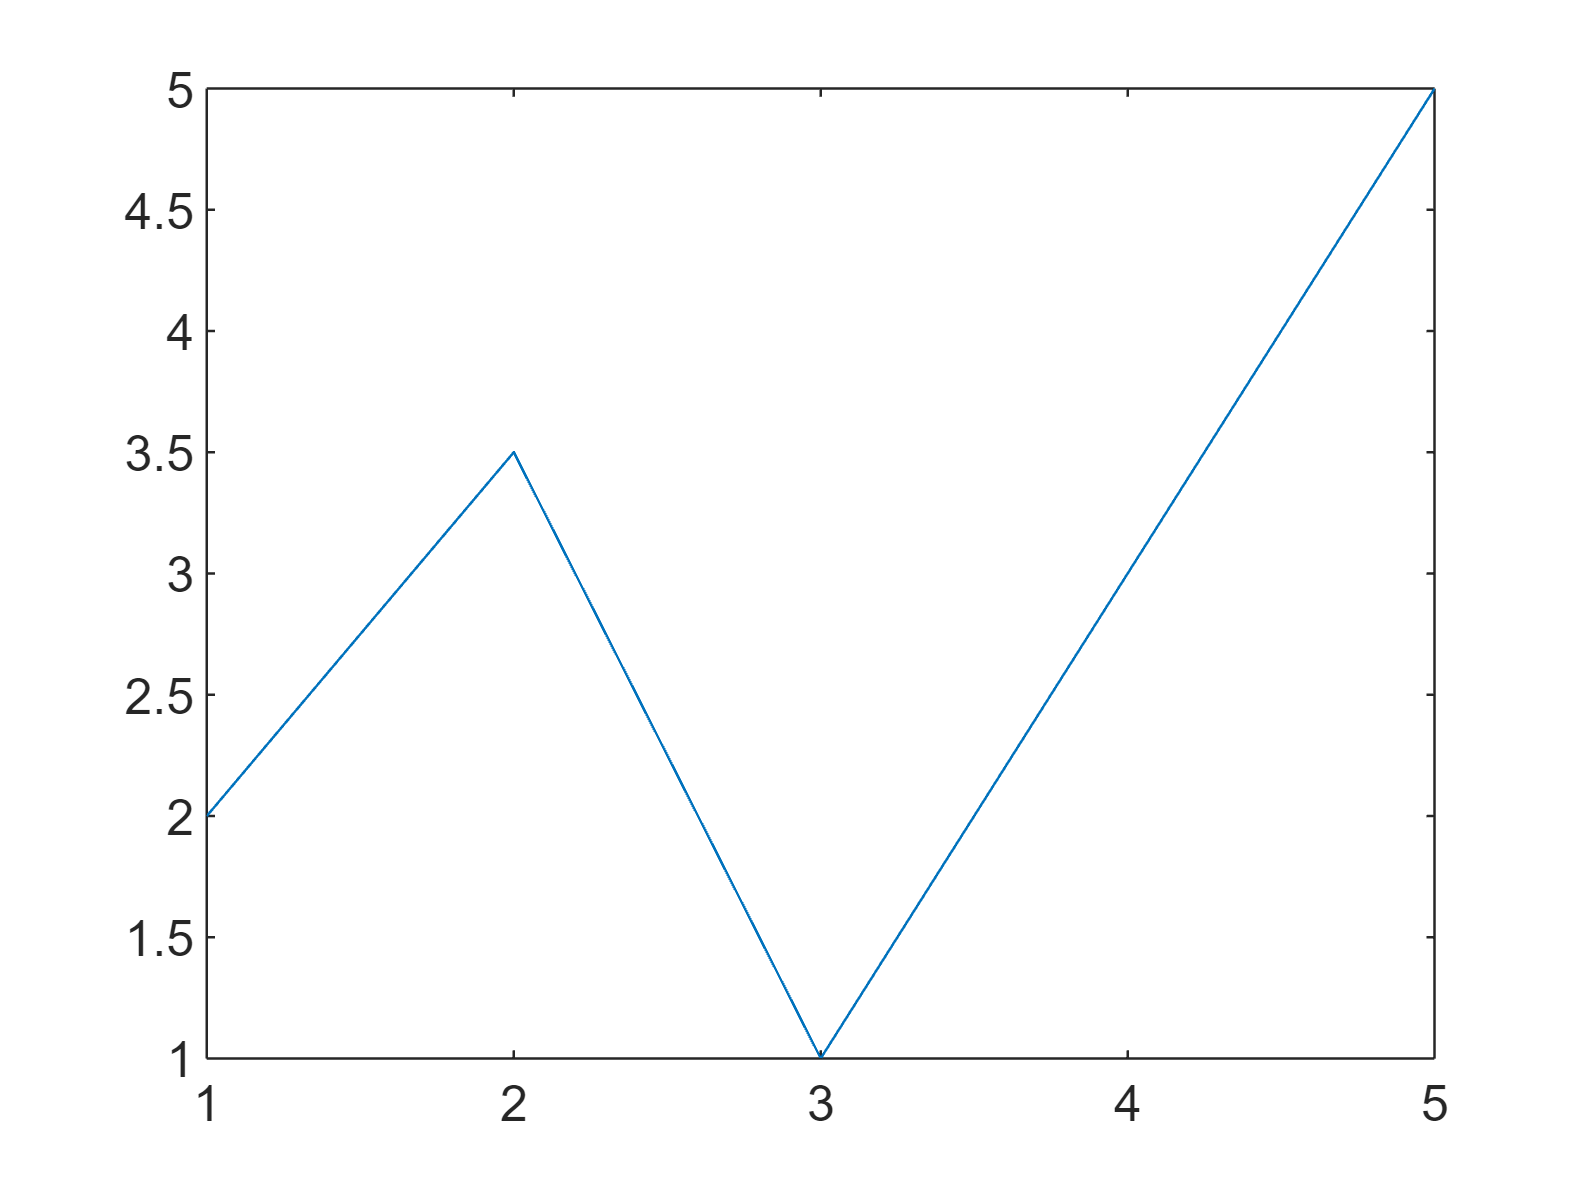

X = [1 2 3 5];
Y = [2 3.5 1 5];
plot(X,Y)

- mostrar varias gráficas distintas en una misma figura:

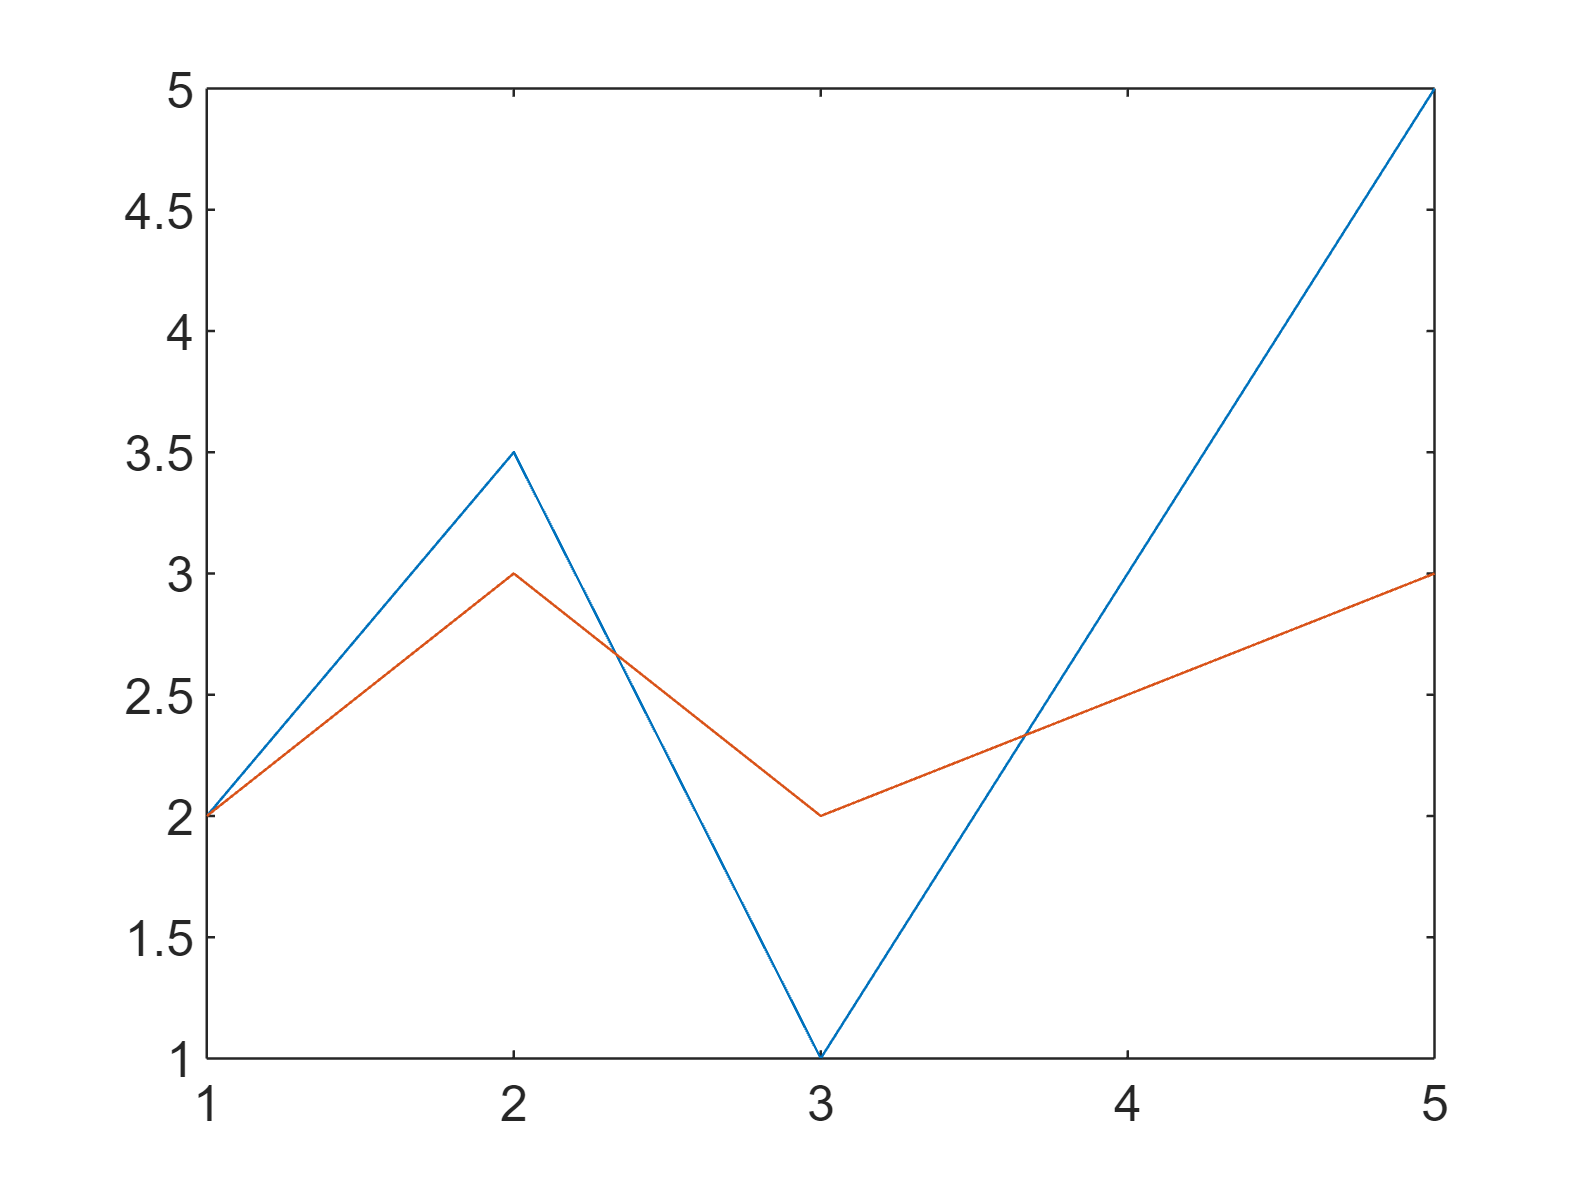

X2 = [1 2 3 5];
Y2 = [2 3 2 3];
plot(X,Y,X2,Y2)

Por defecto MATLAB conecta cada uno de los puntos en los vectores anteriores con una línea, este comportamiento se puede modificar incluyendo un **símbolo** que represente dichos puntos:

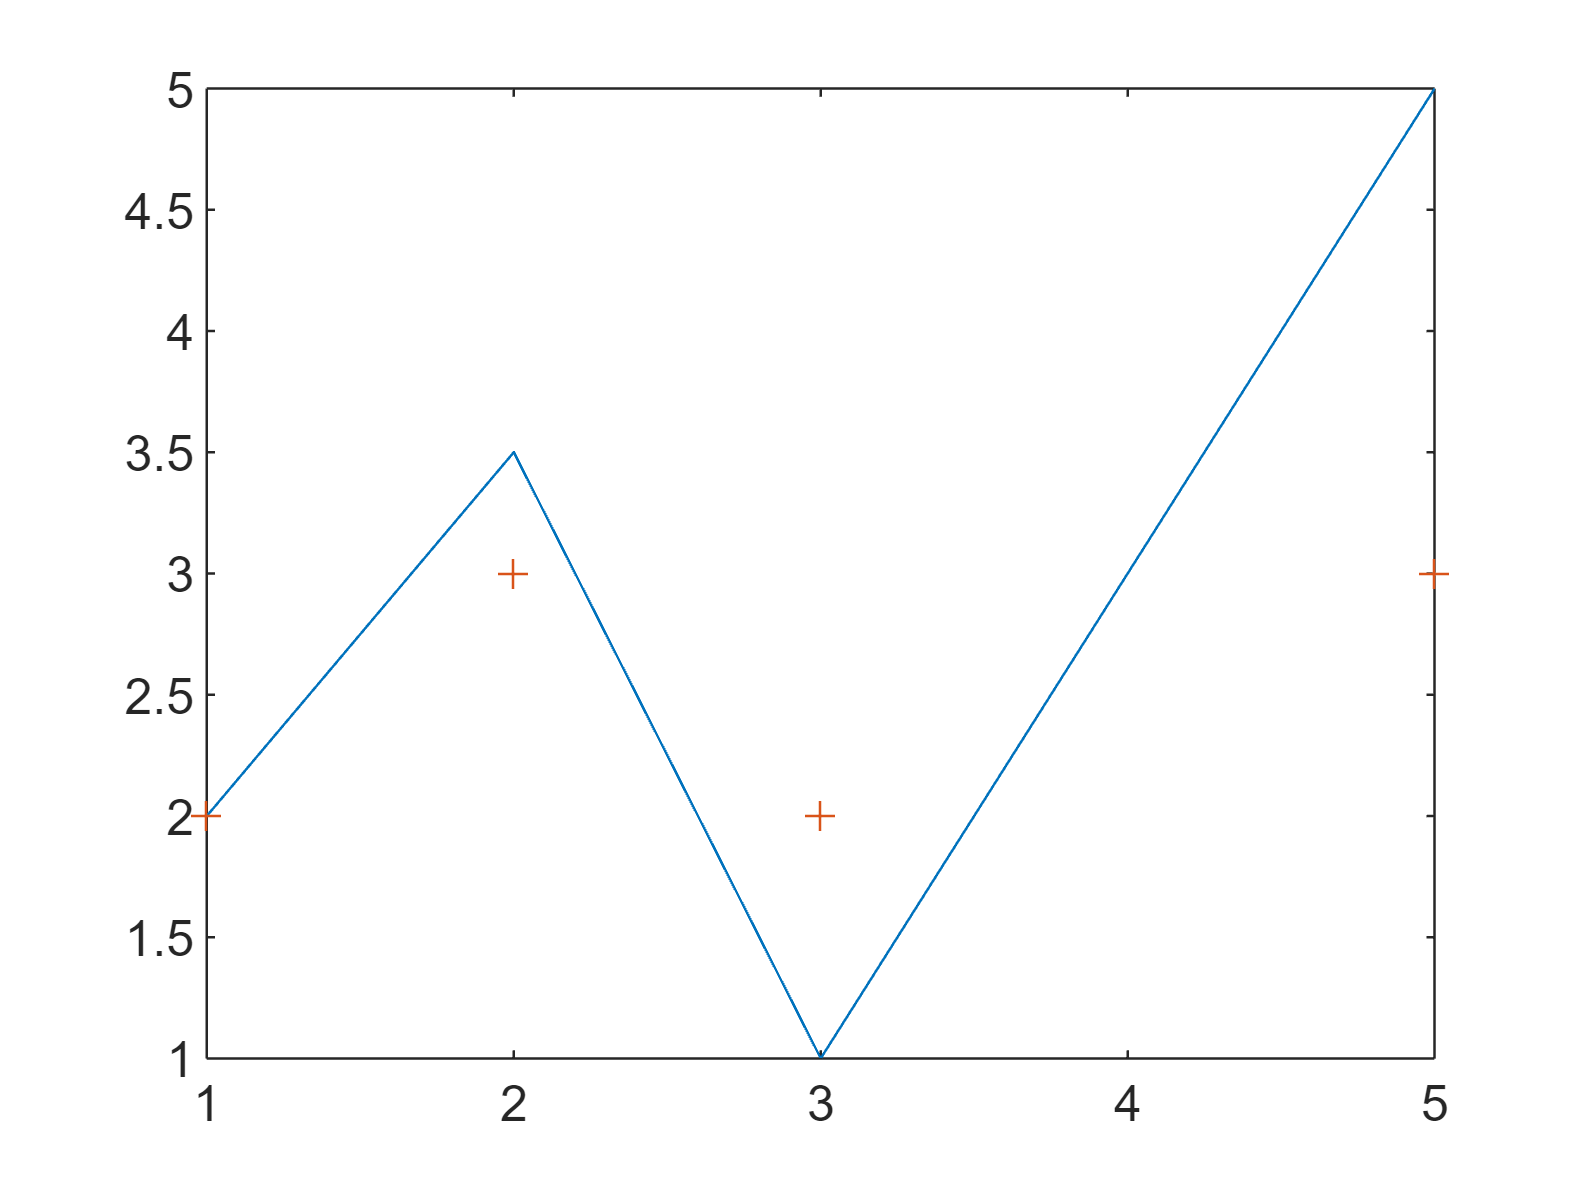

plot(X,Y,X2,Y2,'+')

Otra posibilidad de personalización de las gráficas es elegir el **color** de estas. Por ejemplo para pintar en magenta:

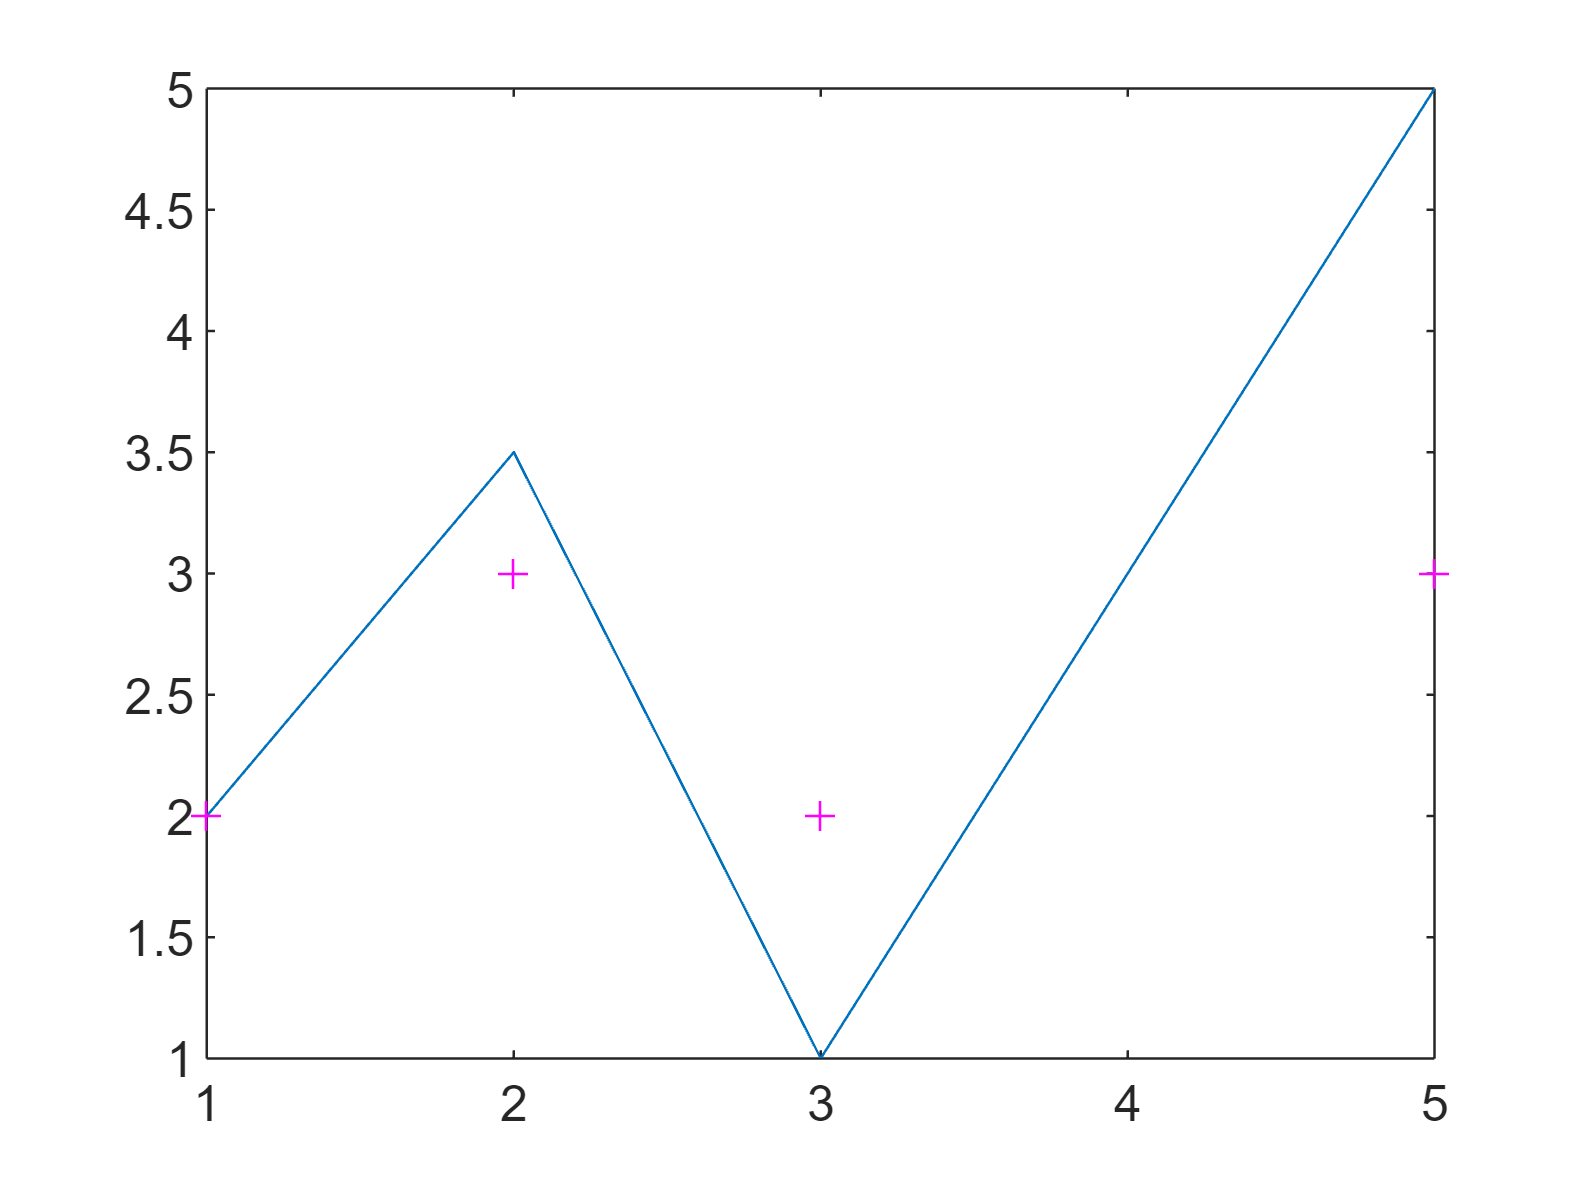

plot(X,Y,X2,Y2,'+m')

Puedes consultar la documentación de MATLAB para comprobar los símbolos y colores que hay disponibles.

### `Algunas funcionalidades interesantes`

De manera genérica, MATLAB ofrece una serie de comandos para trabajar con gráficos:

- `clf`: Borra la ventana gráfica activa. 

- `figure`: Abre una ventana gráfica y le asigna el papel de ventana gráfica activa.  

- `ginput`: Permite extraer, utilizando el ratón, las coordenadas de una serie de puntos situados sobre un gráfico. La activación de la tecla return finaliza el proceso

- `grid`: Muestra una rejilla sobre la gráfica situada en la ventana gráfica activa. 

- `hold`: hold on hace que todos los gráficos sucesivos cuyo trazado sea ordenado se incluyan en la ventana gráfica activa. hold off deshace este efecto. 

**Tarea 1:** Obtener una representación gráfica en el color magenta de la función $y=\sin \left(\theta \right)$para los valores de $\theta$ comprendidos en el intervalo $\left\lbrack -2\Pi ,8\Pi \right\rbrack$ con una resolución (paso) de un grado. Además, marcar en la misma con un ‘*’ negro el punto en el que ésta alcanza un mínimo en el intervalo de $\theta$ comprendido entre 0 y 10. Asimismo, obtener la integral definida de dicha función en el intervalo de $\theta$ comprendido entre 1 y 2. 

***Pista:*** necesitarás usar los comandos `sin`, `fminsesarch`, `hold`, y `quad`.

% Siempre que se trabaja con figuras es buena idea abrir una 
% ventana gráfica para evitar continuar "pintando" sobre una
% creada anteriormente
figure
% Tu código aquí 
d = deg2rad(1);
x = (-2*pi:d:8*pi);
% y es la funcion seno
y = sin(x);
plot(x,y,'m');
hold on 
fun = @(x) sin(x);
x0 = 3;
f = fminsearch(fun,x0)

f = 4.7124

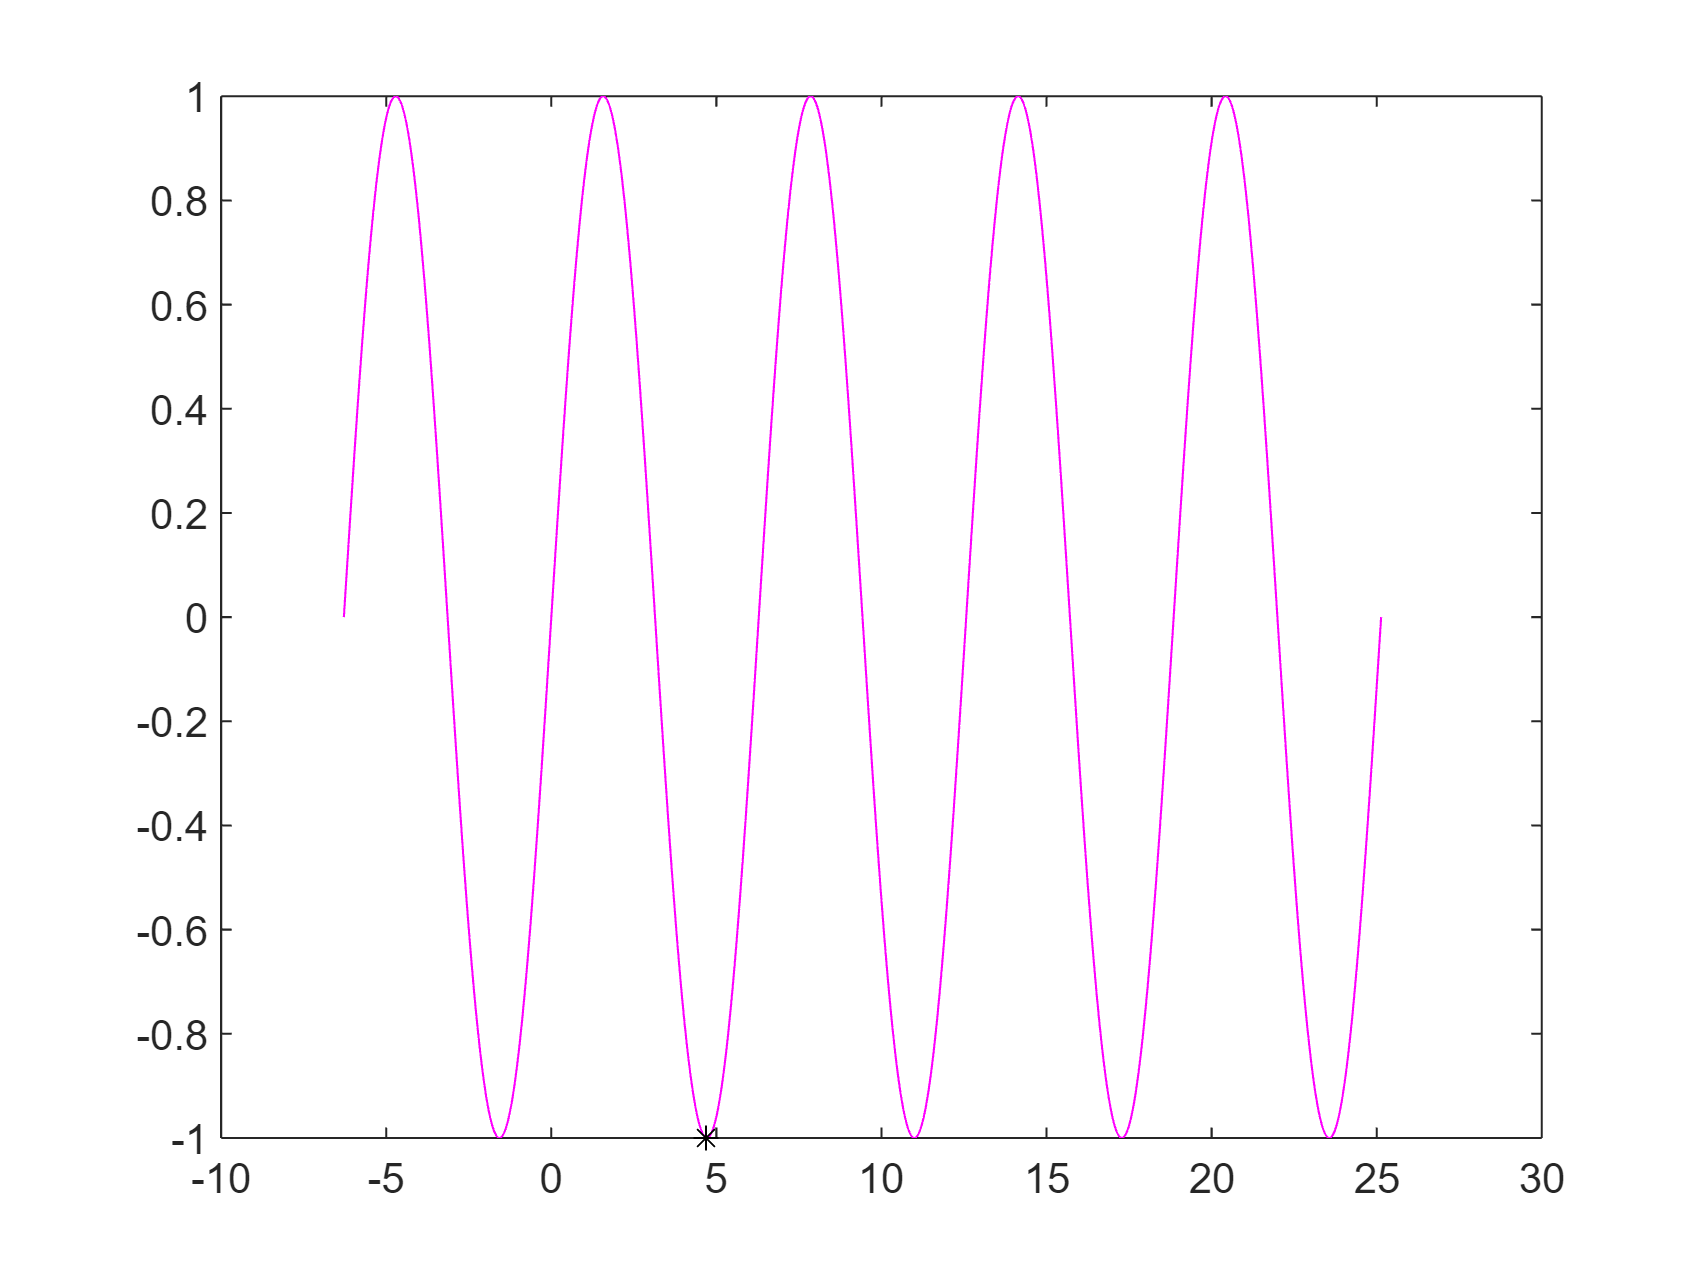

g = sin(f);
plot(f,g,'*k')
hold off 

help quad 

 quad - (Not recommended) Numerically evaluate integral, adaptive Simpson quadrature
    This MATLAB function approximates the integral of function fun from a to
    b using recursive adaptive Simpson quadrature:

    Syntax
      q = quad(fun,a,b)
      q = quad(fun,a,b,tol)
      q = quad(fun,a,b,tol,trace)
      [q,fcnEvals] = quad(___)

    Input Arguments
      fun - Integrand
        function handle
      a - Integration limits (as separate arguments)
        scalars
      b - Integration limits (as separate arguments)
        s

integral = quad(fun,1,2)

integral = 0.9564

`Resultado esperado:`

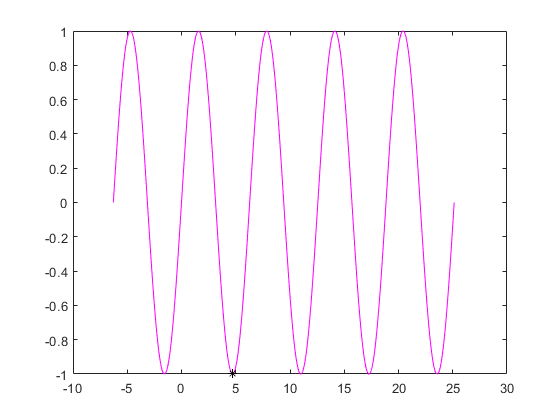

`integral = 0.9564`

## `2. Subgráficas`

Pero, ¿qué pasa si necesito mostrar gráficas distintas simultáneamente? No hay problema, MATLAB ha pensado en todo y mediante el comando `subplot `podemos dividir la ventana gráfica activa en una serie de particiones horizontales y verticales, activando una de ellas. Si no hay ventana gráfica activa, la crea. 

Veamos el siguiente código de ejemplo que divide la ventana gráfica en 2 filas con 2 gráficos cada una (el tercer argumento de `subplot` indica el índice de la subgráfica que se va a activar para *pintar* en ella):

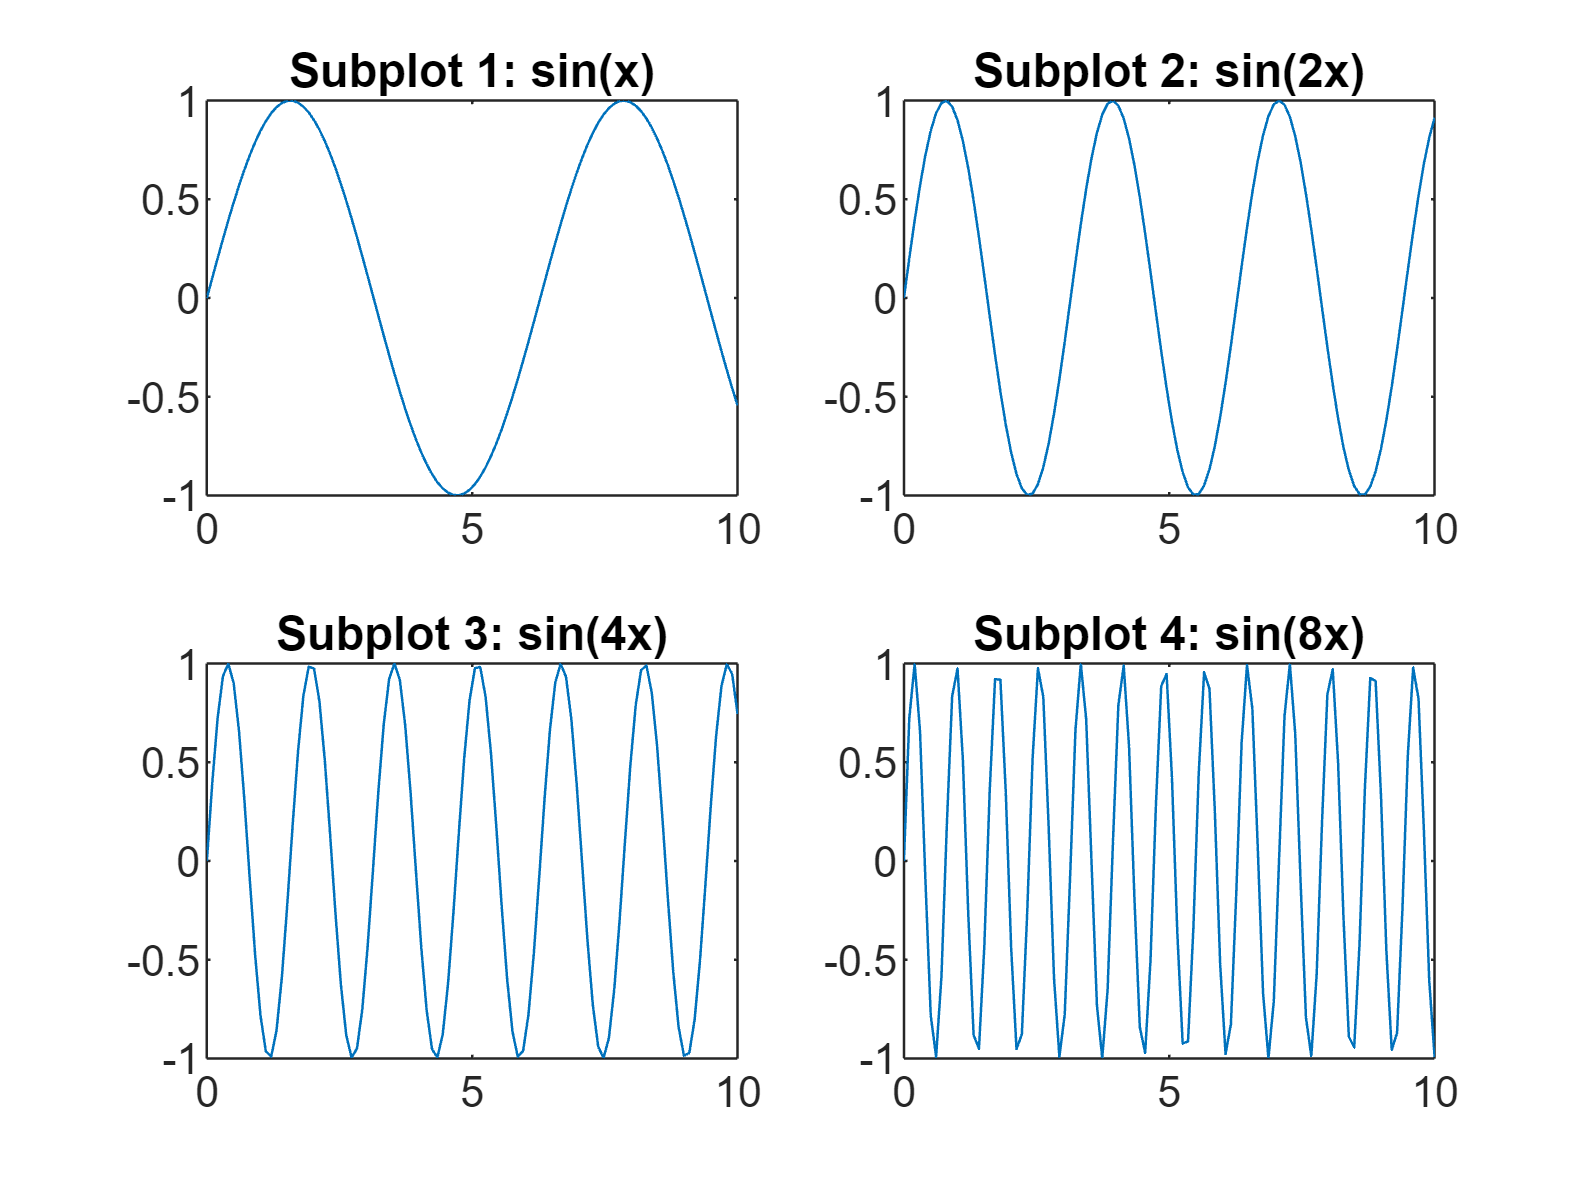

subplot(2,2,1)
x = linspace(0,10);
y1 = sin(x);
plot(x,y1)
title('Subplot 1: sin(x)')

subplot(2,2,2)
y2 = sin(2*x);
plot(x,y2)
title('Subplot 2: sin(2x)')

subplot(2,2,3)
y3 = sin(4*x);
plot(x,y3)
title('Subplot 3: sin(4x)')

subplot(2,2,4)
y4 = sin(8*x);
plot(x,y4)
title('Subplot 4: sin(8x)')

**Tarea 2:** Obtener una representación gráfica de las funciones $y_1 =3\sin \left(\theta \right)$, $y_2 =4\cos \left(\theta \right)$ y la suma de ambas $y_3 =y_1 +y_2$ para los valores de $\theta$ comprendidos en el intervalo $\left\lbrack 0,4\Pi \right\rbrack$, con una resolución de un grado, en cada una de las formas siguientes: 

- a) En una única ventana gráfica utilizando los mismos ejes y colores diferentes. 

- b) En una única ventana gráfica (figura) donde podrán visualizarse las tres gráficas alineadas verticalmente. 

***Pista:*** Entre los comandos a utilizar necesitarás recurrir a `figure`.para ir creando las nuevas figuras.

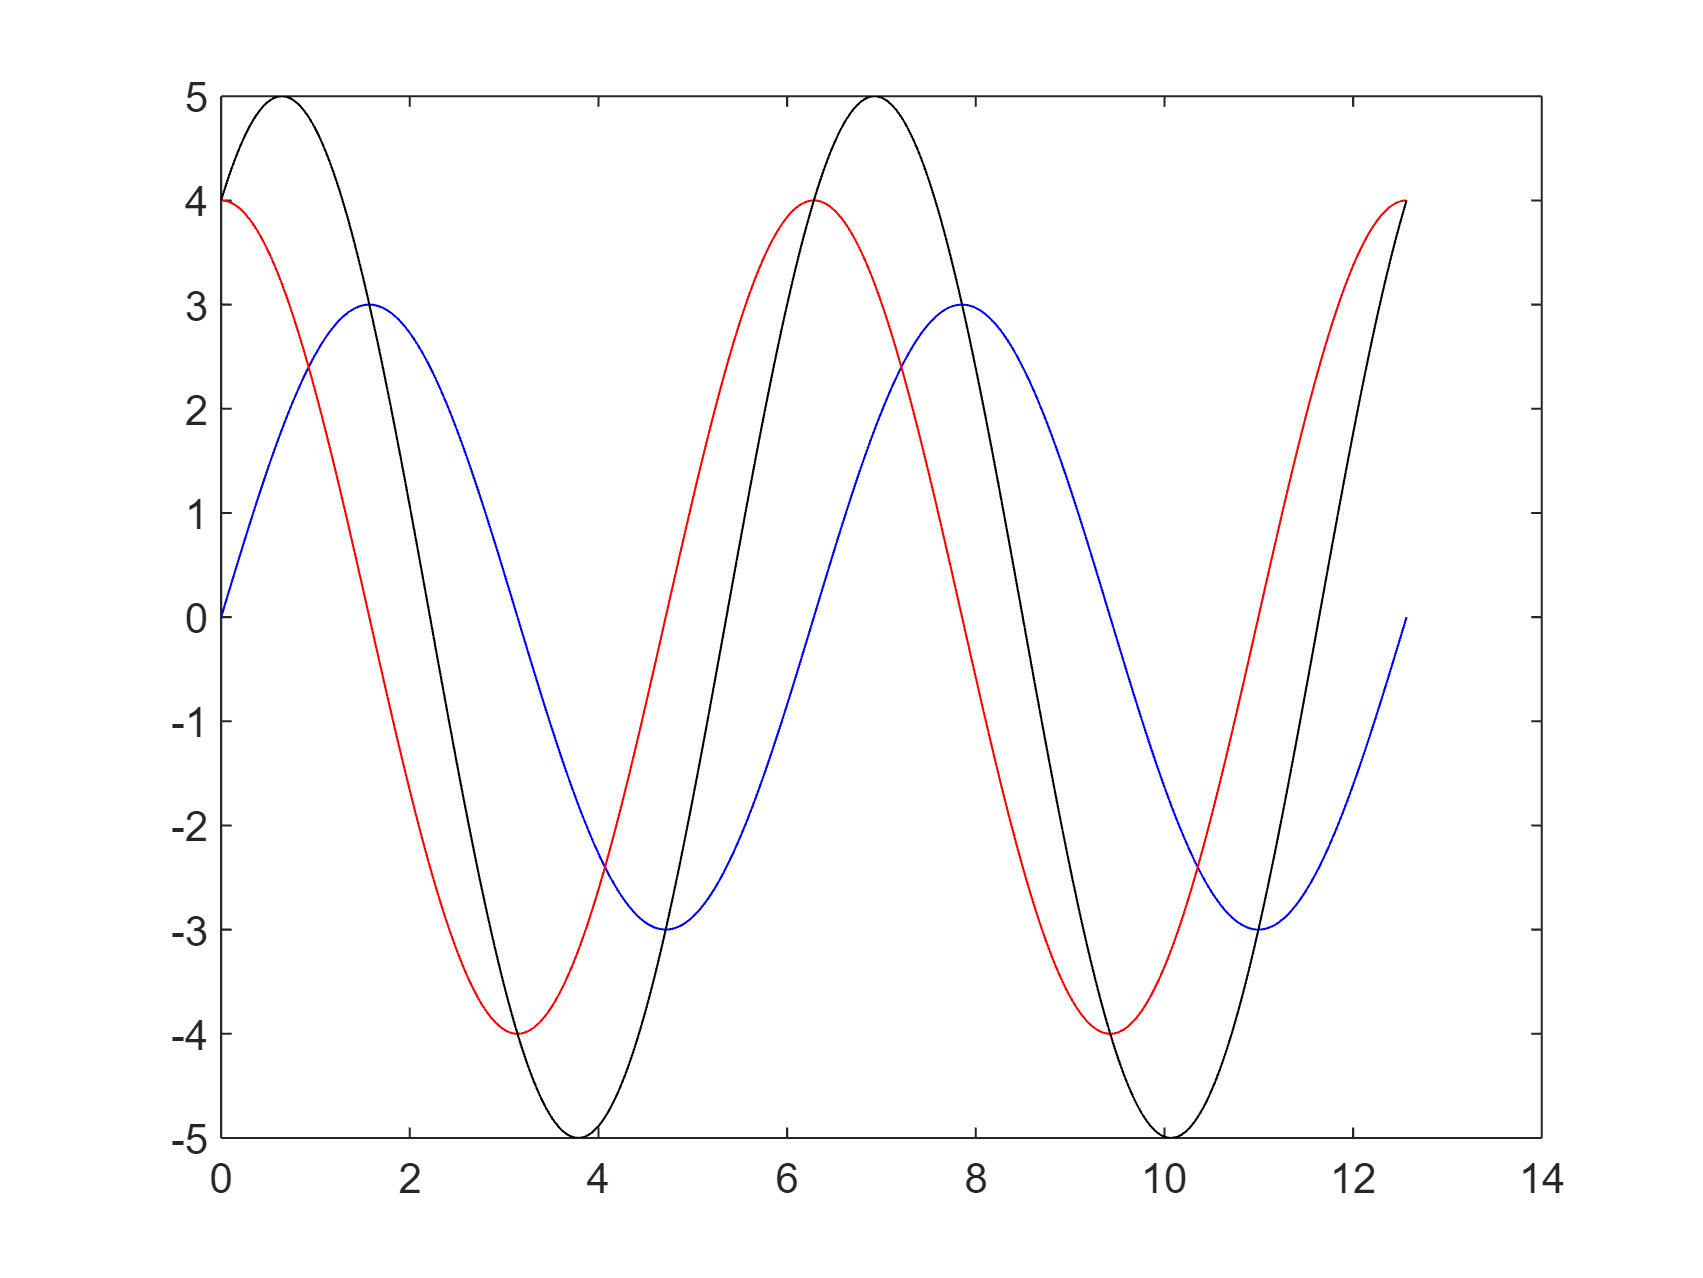

% Tu código aquí

% a) 
figure
d = deg2rad(1);
x = (0:d:4*pi);
y1 = 3*sin(x);
y2 = 4*cos(x);
y = y1 + y2;
plot(x,y1,"b",x,y2,"r",x,y,"k")

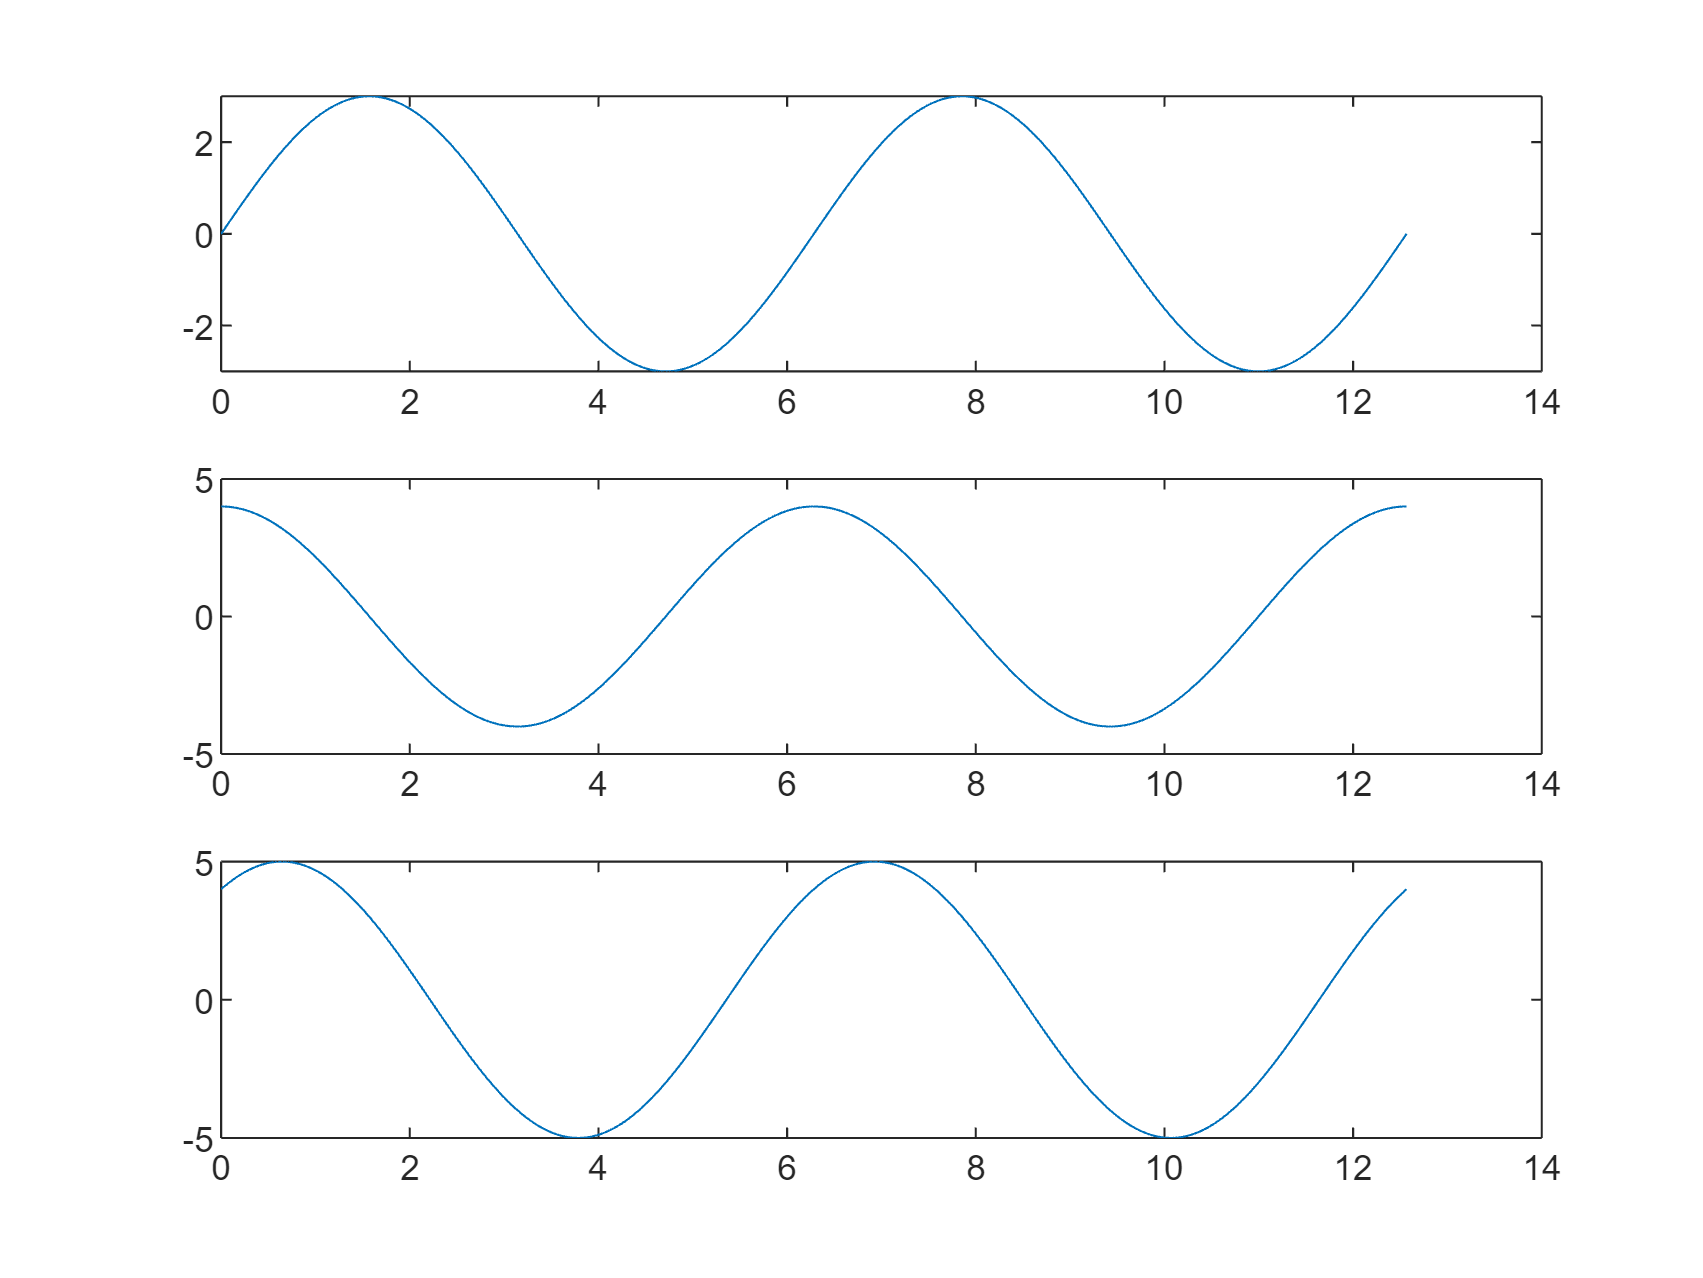


%b)
figure
subplot(3,1,1)
d = deg2rad(1);
x = (0:d:4*pi);
y1 = 3*sin(x);
plot(x,y1)
subplot(3,1,2)
y2 = 4*cos(x);
plot(x,y2)
subplot(3,1,3)
y = y1 + y2;
plot(x,y)

*Resultado esperado:*

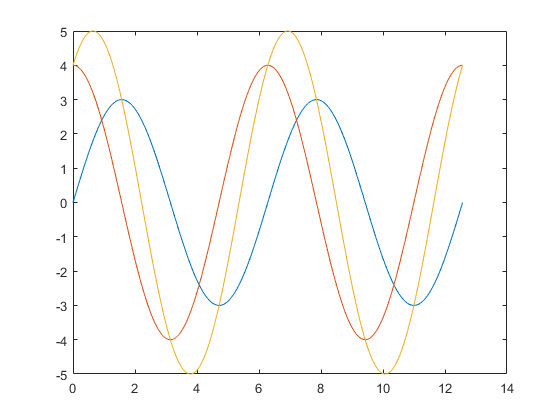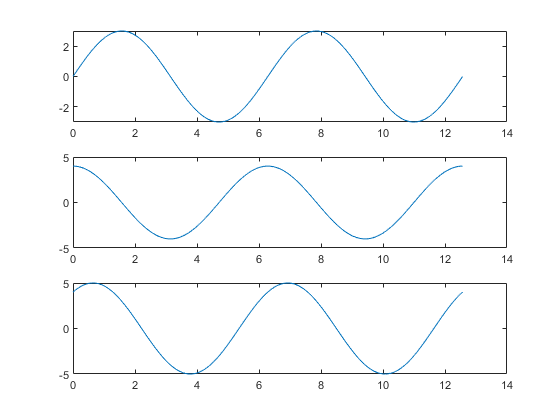

## `3. Control sobre los ejes`

MATLAB provee de una serie de funciones, equivalentes a `plot`, que permiten especificar la escala de los ejes. Por ejmplo:

- `loglog`: tanto el eje de abcisas como el de ordenadas se representan en escala logarítmica decimal.

- `semilogx`: el eje de abcisas se representa en escala logarítmica decimal.

- `semilogy`: el eje de ordenadas se representa en escala logarítmica decimal.

Además, también es posible poner un título a la gráfica con el comando `title `(habrá que usar `sgtitle `si se le quiere poner título a una figura que contiene `subfigure`**)**, así como un texto junto al eje de abcisas (`xlabel`) o de ordenadas (`ylabel`).

Para finalizar con los ejes, también está disponible la función `axis`. Vamos a ver en qué consiste:

help axis

 axis - Set axis limits and aspect ratios
    This MATLAB function specifies the limits for the current axes.

    Syntax
      axis(limits)

      axis style
      axis mode
      axis ydirection
      axis visibility

      lim = axis
      [m,v,d] = axis('state')

      ___ = axis(ax,___)

    Input Arguments
      limits - Axis limits
        four-element vector | six-element vector | eight-element vector
      mode - Manual, automatic, or semiautomatic selection of axis limits
        manual | auto | 'auto x' | 'auto y' | 'auto z' | 'auto xy' |
        'auto xz' | 'auto yz'
      

**Tarea 3:** Se desea representar gráficamente la función $y=5\log_{10} x$ para los valores de $x$ comprendidos en el intervalo $\left\lbrack 0\ldotp 1,10\right\rbrack$, con una resolución de una décima. Obtener en una única ventana gráfica, utilizando ejes diferentes alineados verticalmente, una representación de dicha función en cada una de las formas siguientes: 

- a) Utilizando escalas lineales en ambos ejes. 

- b) Utilizando escala logarítmica decimal para el eje de abcisas y escala lineal para el eje de ordenadas. 

Además, ponle el título que desees.

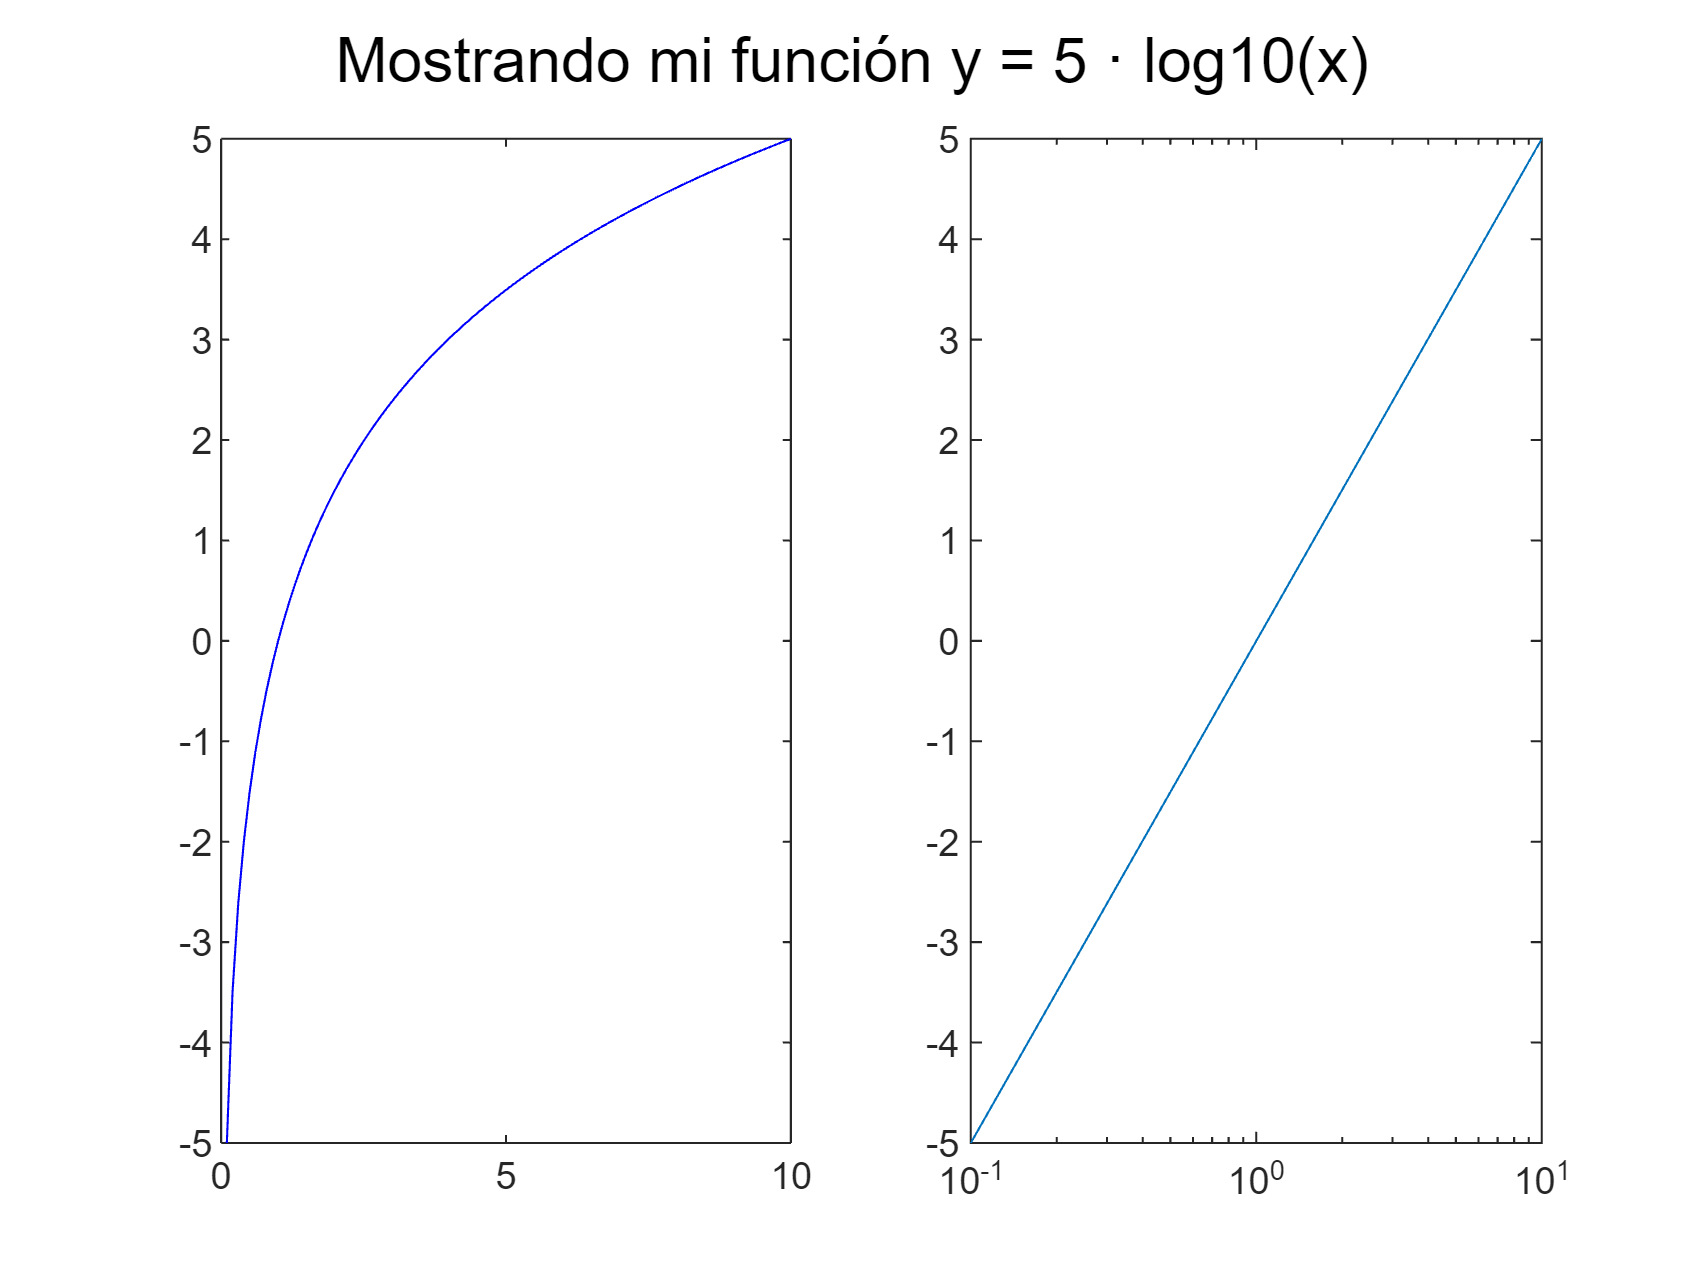

% Tu código aquí
figure 
sgtitle('Mostrando mi función y = 5 · log10(x)')
subplot(1,2,1)
x = 0.1:0.1:10;
fun = @(x) 5*log10(x);
y = 5*log10(x);
plot(x,y,'b')
subplot(1,2,2)
semilogx(x,y) 

`Resultado esperado:`